Lab 1: Magnetoptik

Grego Jaca, Peti Tallosy

Task 1

no polarizer

max_voltage = 5.8185 V

polarizer

min_V = 66mV+-1mV

%sweep
% considering background light: about 11mV diff with pullover covered in min values
voltage_offset = 65;

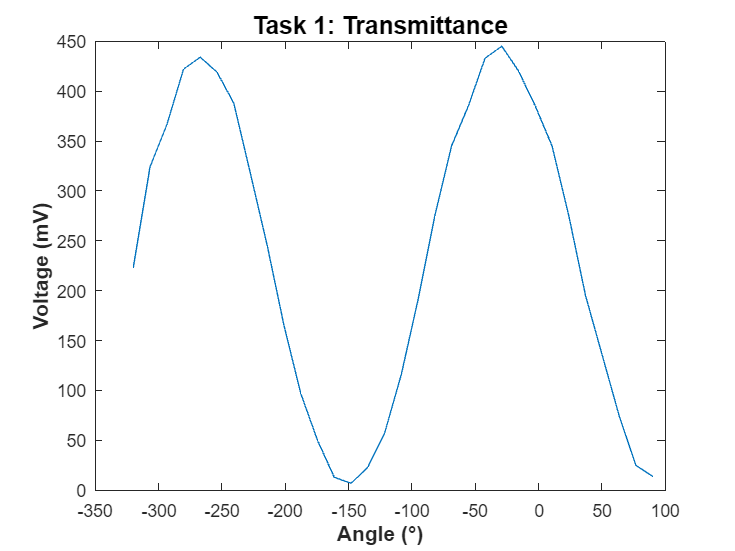

% this one was not so accurate
% background light high
voltage = [79, 90, 140, 200, 260, 340, 410, 450, 485, 510, 498, 450, 410, 340, 256, 181, 122, 88, 72, 78, 115, 162, 230, 310, 382, 453, 484, 499, 487, 431, 389, 288] - voltage_offset; % +-5 mV 
angle = linspace(90, -length(voltage)*10, length(voltage)); % +- 3 degrees

plot((angle), voltage);
xlabel('Angle (°)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Voltage (mV)', 'FontSize', 12, 'FontWeight', 'bold');
title('Task 1: Transmittance', 'FontSize', 14, 'FontWeight', 'bold');


extintion_ratio = min(voltage) / max(voltage)

extintion_ratio = 0.0157


%extintion_ratio = (min(voltage)-voltage_offset) / (max(voltage)-voltage_offset)

we set the angle 0 to be the parallel orientation of the polarizer (and 90 the perpendicular)

the plot shows a cos squared dependency of the light intensity (which is proportional to the detector voltage) wrt angle. the extintion_ratio is reasonable given that we took the min and max intensity using 10 degree steps.

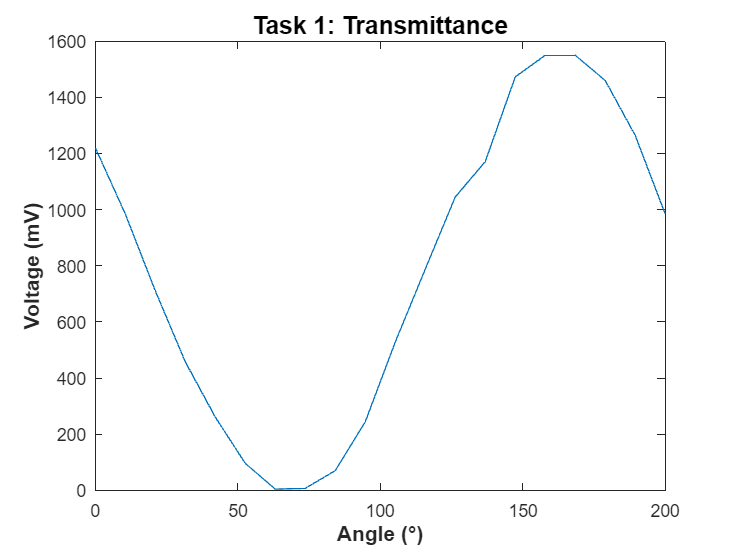

% this is more accurate
voltage = [1286, 1050, 776, 523, 326, 161, 69, 72, 135, 309, 593, 853, 1110, 1236, 1538, 1615, 1615, 1525, 1329, 1049] - voltage_offset; % mV +- 5mV

angle = linspace(0, length(voltage)*10, length(voltage)); % degree; +- 3 degrees
plot((angle), voltage);
xlabel('Angle (°)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Voltage (mV)', 'FontSize', 12, 'FontWeight', 'bold');
title('Task 1: Transmittance', 'FontSize', 14, 'FontWeight', 'bold');

extintion_ratio = min(voltage) / max(voltage)

extintion_ratio = 0.0026

at 65 degrees we experience the minimum intensity. at - 30 the maximum

Task 2

now we add the LC and rotate it until we find the max intensity

at 43 degrees the LC yields max intensity 1360mV

we rotated the analyzer 90 degrees and observed meas voltages: 75mV

now again rotated the LC and observed at 93 degrees we meas max voltage of 854mV.

The rotation of the LC was aprox 50 degrees, significantly more than the 45 we were expecting. The manual tuning to find the orientation is not so exact.

now we rotate the analyzer and measure

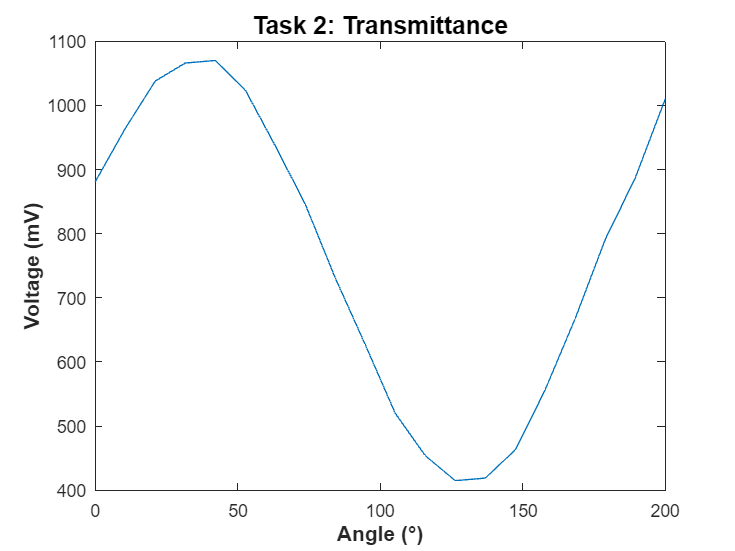

% instead of rotating 90 degrees, we rotated it 120 degrees. we noticed
% when we saw a big intensity reduction (while doing this plot below, of
% the angular dependency), which was unexpected.
% then we noticed and corrected everzthing.
voltage = [946, 1029, 1103, 1131, 1135, 1089, 1002, 911, 796, 692, 585, 519, 480, 484, 528, 622, 733, 856, 952, 1075] - voltage_offset; % +-5 mV 
angle = linspace(0, length(voltage)*10, length(voltage)); % degree; +- 3 degrees
plot((angle), voltage);
xlabel('Angle (°)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Voltage (mV)', 'FontSize', 12, 'FontWeight', 'bold');
title('Task 2: Transmittance', 'FontSize', 14, 'FontWeight', 'bold');

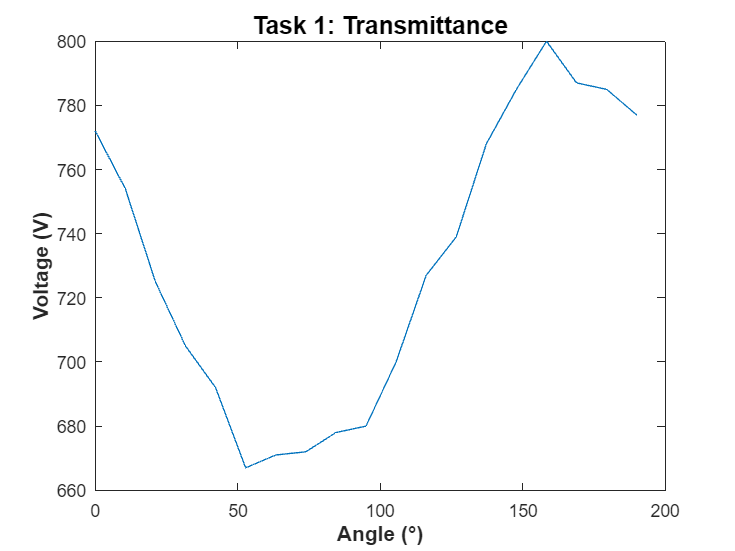

% here we did it correctly (lie)
voltage = [837, 819, 790, 770, 757, 732, 736, 737, 743, 745, 765, 792, 804, 833, 850, 865, 852, 850, 842] - voltage_offset; % +-5 mV 
angle = linspace(0, length(voltage)*10, length(voltage)); % degree; +- 3 degrees
plot((angle), voltage);
xlabel('Angle (°)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Voltage (V)', 'FontSize', 12, 'FontWeight', 'bold');
title('Task 1: Transmittance', 'FontSize', 14, 'FontWeight', 'bold');

now we add the LC and rotate it until we find the max intensity

at 141 degrees the LC yields max intensity 1467mV

we rotated the analyzer 90 degrees and observed meas voltages: 75mV

now again rotated the LC and observed at 91 degrees we meas max voltage of 793mV.

The rotation of the LC was aprox 50 degrees, significantly more than the 45 we were expecting. The manual tuning to find the orientation is not so exact.

now we rotate the analyzer and measure

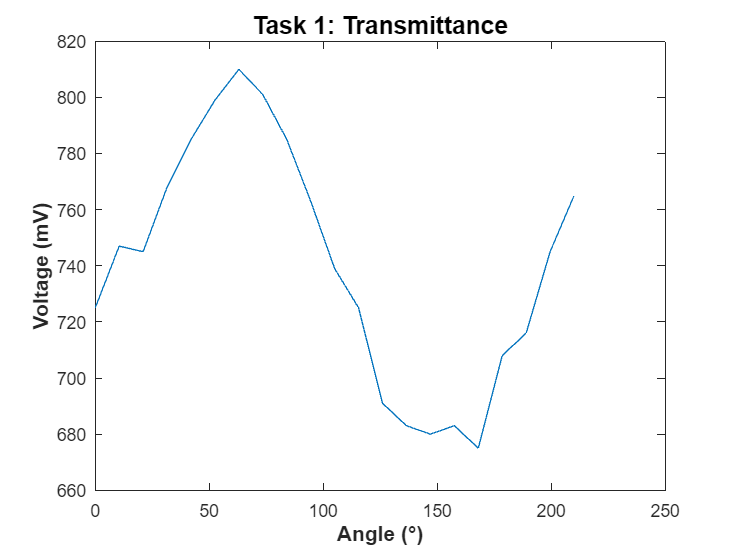

% here we did it correctly
voltage = [790, 812, 810, 833, 850, 864, 875, 866, 850, 828, 804, 790, 756, 748, 745, 748, 740, 773, 781, 810, 830] - voltage_offset; % +-5 mV 
angle = linspace(0, length(voltage)*10, length(voltage)); % degree; +- 3 degrees
plot((angle), voltage);
xlabel('Angle (°)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Voltage (mV)', 'FontSize', 12, 'FontWeight', 'bold');
title('Task 1: Transmittance', 'FontSize', 14, 'FontWeight', 'bold');

we see an angular dependency but the difference between the maximum and minimum values is small. the angular dependency is small. the LC is polarizing most of the light circularly (this was done by the aprox 45 degree rotation) and when it reaches the analyzer filter, which is a linear filter, the intensity reduction is small. this is consistent with our expectation

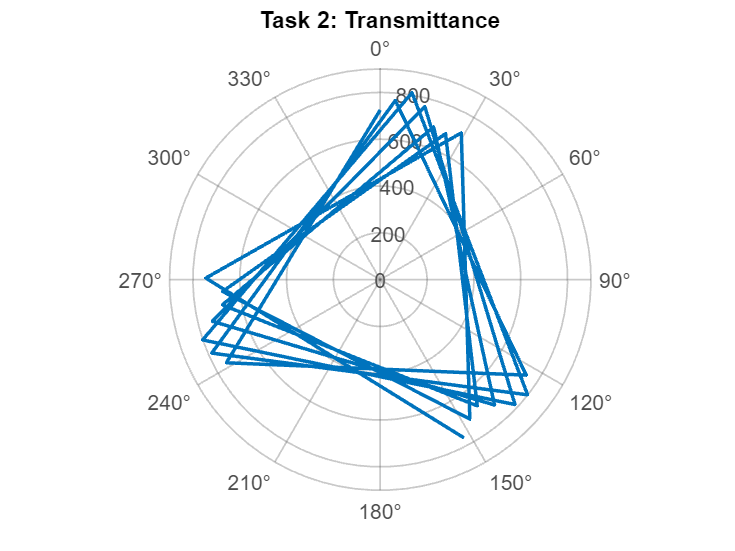

% Polar plot of angle vs voltage
figure;
polarplot(angle, voltage, 'LineWidth', 2, 'Color', [0 0.45 0.74]);

title('Task 2: Transmittance', 'FontSize', 14, 'FontWeight', 'bold');

ax = gca;
ax.ThetaZeroLocation = 'top';     
ax.ThetaDir = 'clockwise';         
ax.FontSize = 12;                   
ax.LineWidth = 1;                   
ax.RColor = [0.3 0.3 0.3];          
ax.ThetaColor = [0.3 0.3 0.3];      
ax.GridAlpha = 0.3;                 

We were expecting a much smaller deviation when doing this. we re did this 3 times trying to improve it but this is the best we got.

we expected an almost constant voltage and circular polar plot

task 3

f = 2 % kHz, rect

f = 2

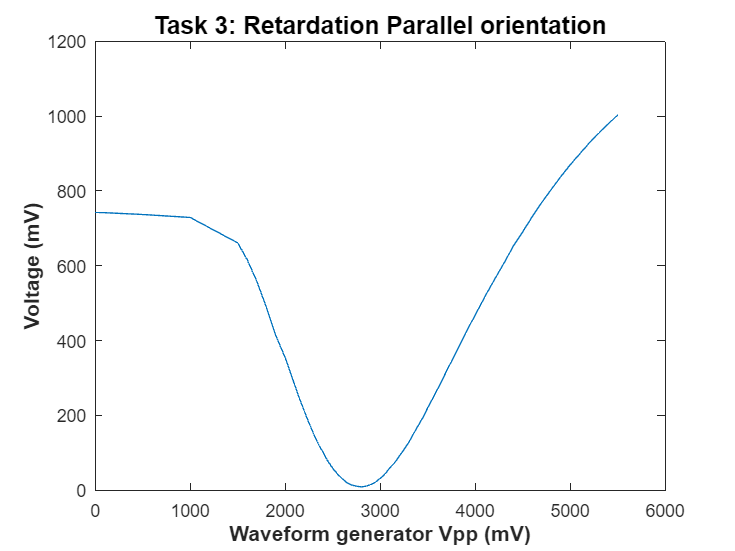


input1 = [0, 500, 1000, 1500, 1600, 1700, 1800, 1900, 2000, 2050, 2100, 2150, 2200, 2250, 2300, 2350, 2400, 2450, 2500, 2550, 2600, 2650, 2700, 2750, 2800, 2850, 2900, 2950, 3000]; % mV vpp
input = cat(2, input1, linspace(3050, 4000, 20), linspace(4100, 5500, 15));
output = [808, 802, 794, 726, 681, 624, 555, 479, 419, 383, 346, 310, 277, 245, 215, 187, 166, 142, 124, 108, 96, 85, 79, 76, 74, 76, 80, 87, 97, 108, 125, 138, 156, 174, 193, 216, 238, 260, 286, 309, 334, 359, 385, 410, 435, 460, 486, 510, 533, 582, 627, 671, 717, 756, 796, 834, 869, 903, 935, 964, 993, 1020, 1044, 1068] - voltage_offset; % +-2 mV 

plot(input, output)
xlabel('Waveform generator Vpp (mV)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Voltage (mV)', 'FontSize', 12, 'FontWeight', 'bold');
title('Task 3: Retardation Parallel orientation', 'FontSize', 14, 'FontWeight', 'bold');

delta_parallel = 2*sqrt(acos(output/800));
plot(input, delta_parallel)

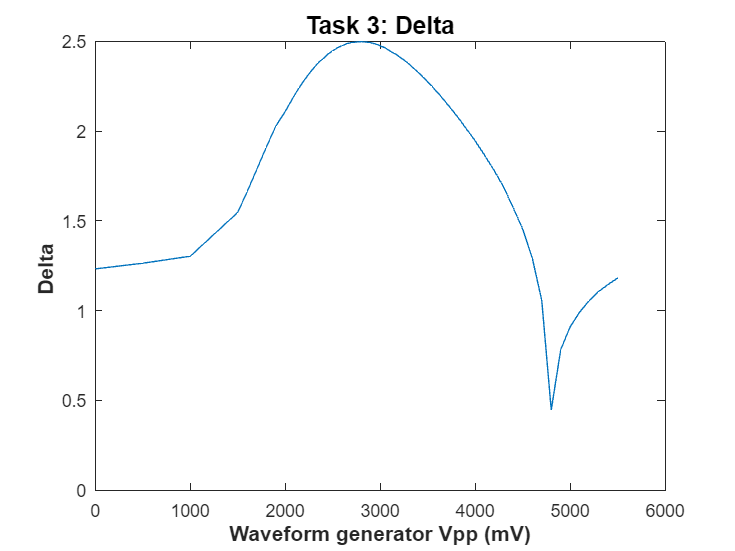

xlabel('Waveform generator Vpp (mV)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Delta ', 'FontSize', 12, 'FontWeight', 'bold');
title('Task 3: Delta', 'FontSize', 14, 'FontWeight', 'bold');

task 4

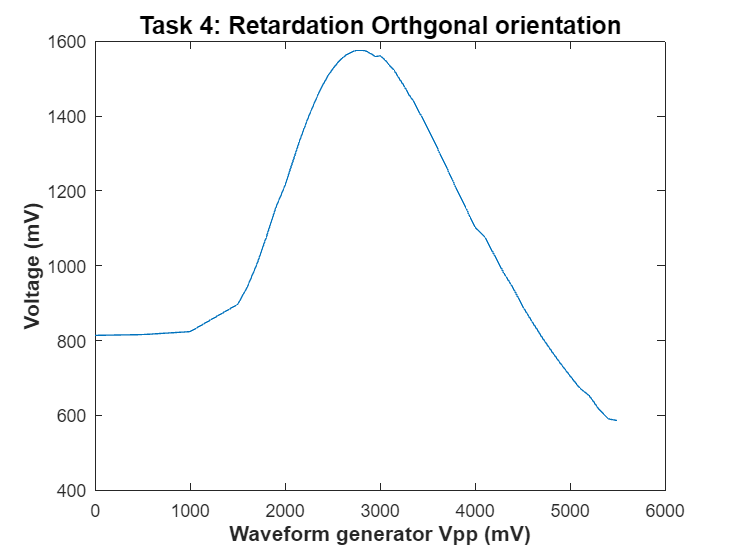

output2 = [814, 816, 824, 897, 943, 1003, 1076, 1155, 1216, 1256, 1294, 1333, 1368, 1401, 1431, 1460, 1485, 1508, 1526, 1542, 1555, 1565, 1571, 1576, 1576, 1574, 1567, 1559, 1561, 1550, 1535, 1521, 1500, 1481, 1458, 1440, 1415, 1392, 1367, 1341, 1315, 1288, 1262, 1234, 1207, 1181, 1155, 1128, 1102, 1077, 1029, 981, 940, 891, 850, 810, 773, 738, 705, 673, 653, 617, 591, 586];
plot(input, output2)
xlabel('Waveform generator Vpp (mV)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Voltage (mV)', 'FontSize', 12, 'FontWeight', 'bold');
title('Task 4: Retardation Orthgonal orientation', 'FontSize', 14, 'FontWeight', 'bold');

We see what we expected, we get all the delta values by changing the applied voltage. this is observed in the plot, as different delta values polarize the light differently and the received light changes. the curves are opposite which is as expected

delta_parallel = 2*sqrt(acos(output/800));
plot(input, delta_parallel)

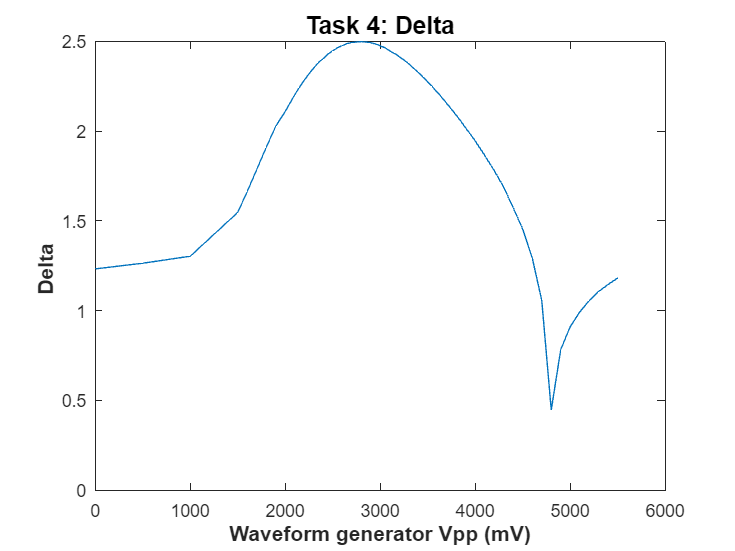

Error using corr
Requires a data matrix X.

xlabel('Waveform generator Vpp (mV)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Delta ', 'FontSize', 12, 'FontWeight', 'bold');
title('Task 4: Delta', 'FontSize', 14, 'FontWeight', 'bold');

task 5

we need to find the optimal awg voltage amplitude for driving the LC. we do it by finding the voltage where we get a single peak

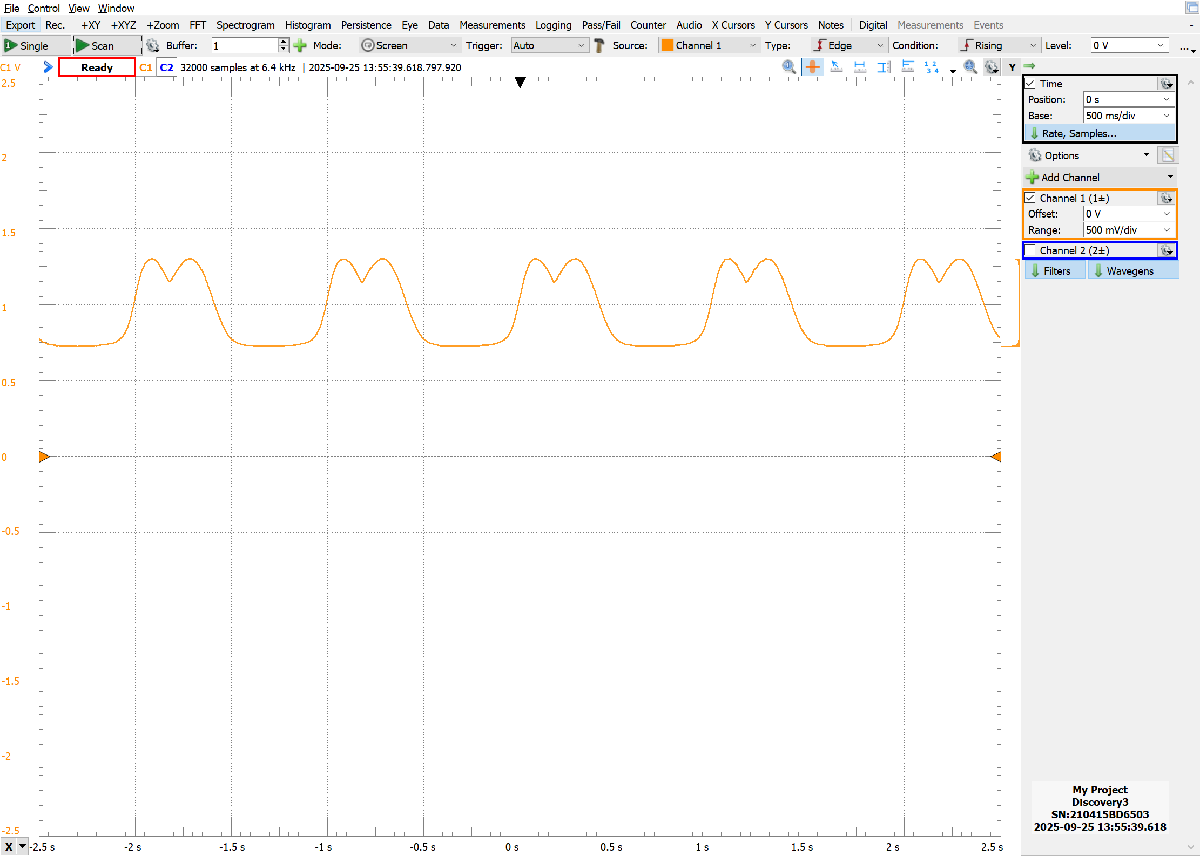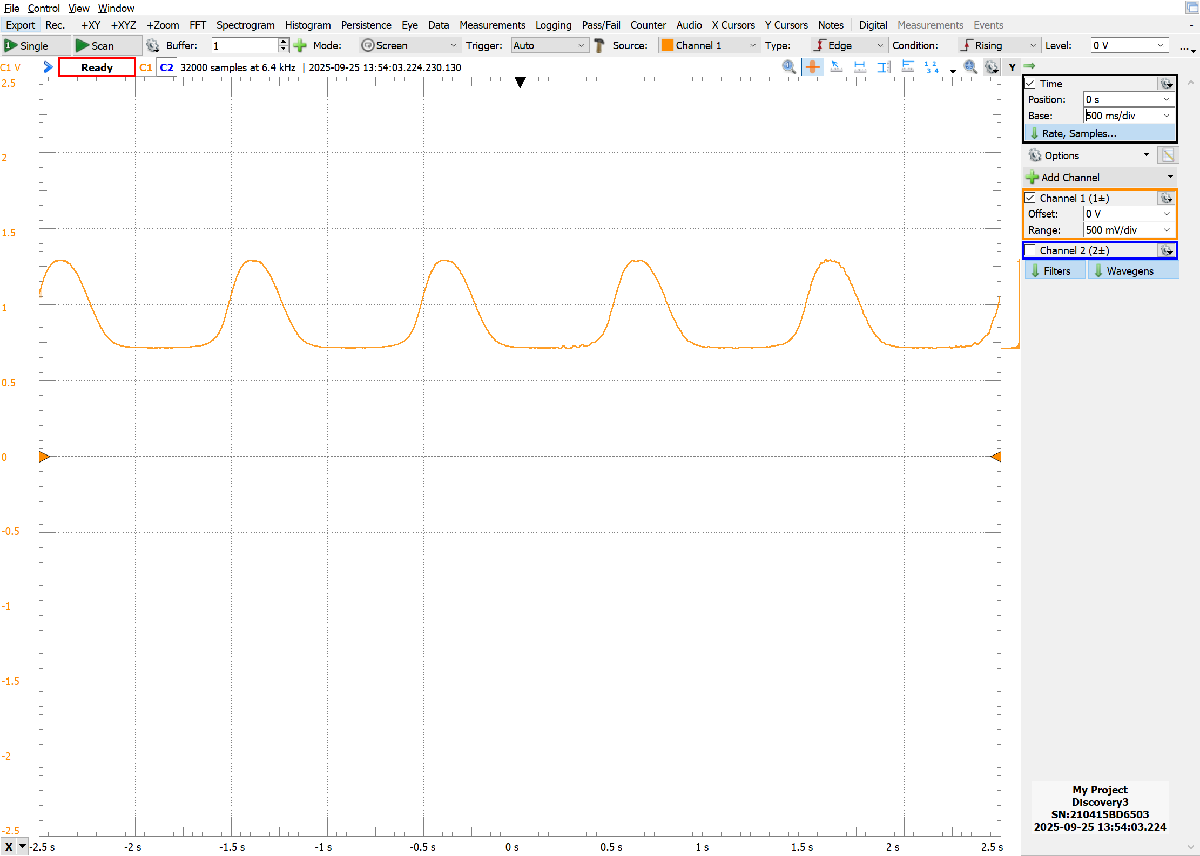

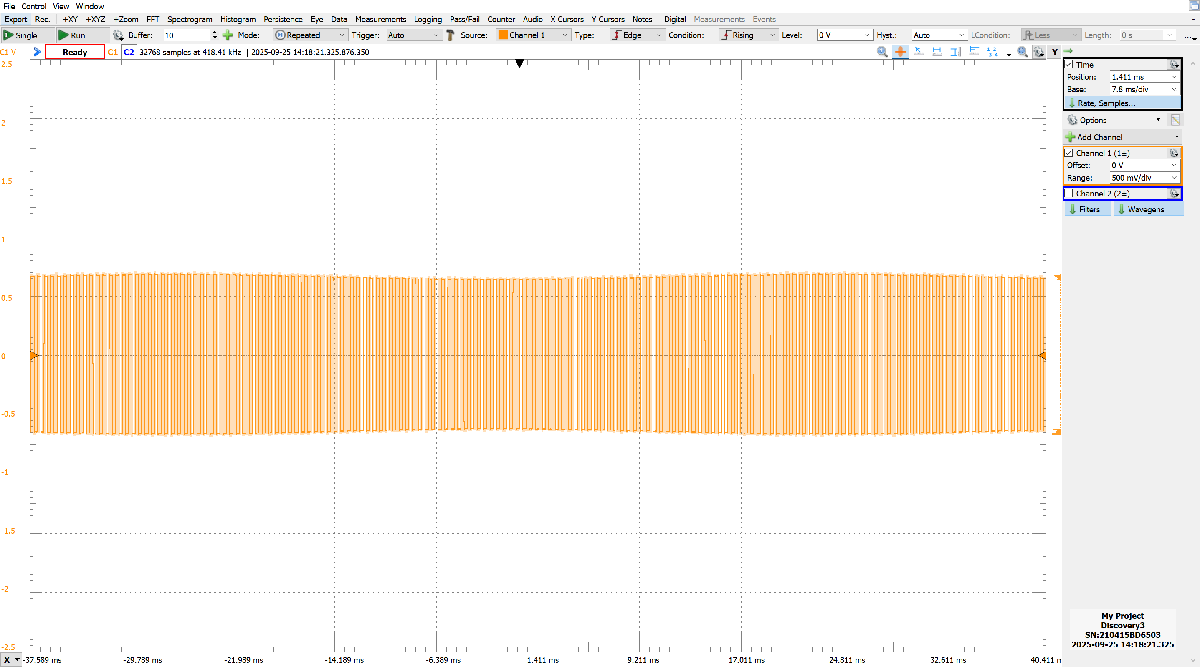

after setting up the orientations based on task 2, 3 and 4 we measure: LC cell mounted at 45 deg to polarizer axis

calibration with lock-in: calibrate the lock-in detection by measuring the 2f harmonic signal as a function of analyzer angle, without sample.

we tried different lock in setups until we could clearly see the bessel functions in the lockin output signal.  the lockin cutoff frequency was one of the most important parameters to determine. we settled on

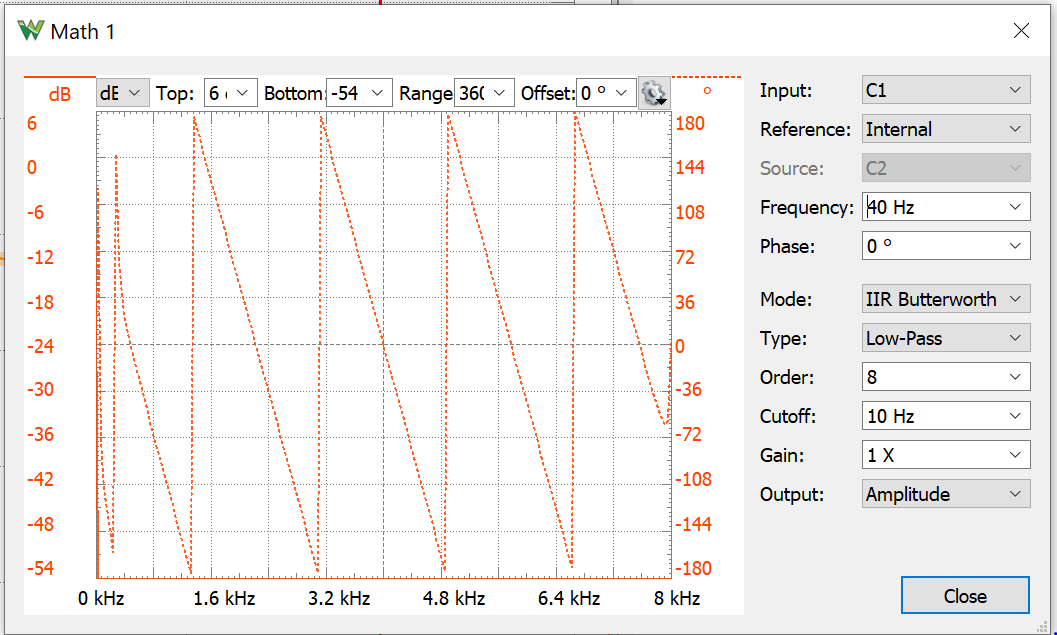 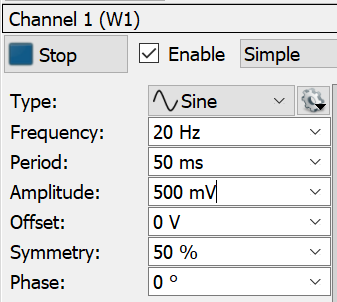

DateTime  2025-09-25

Vpp LC (mV) = 500

 f_mod (Hz) = 20

baseline, room light |

We investigated the sensitivity of the measurement setup by rotating it aprox 10deg around the 45deg baseline. The lockin signal is quite stable, but we could measure the difference in the averages:

by using the locking frequency to twice the modulating frequency we are locking in on the second harmonic

most sensitive param: freq, threshold

Task 6

we observed

vertical_d

C1	Visible	Average	 96.327 mV

M1	Visible	Average	 421.10 uV

M1	X1 X2	Average	 112.15 uV

horiz_d

C1	Visible	Average	 95.482 mV

M1	Visible	Average	 477.27 uV

M1	X1 X2	Average	 182.59 uV

horizontal_empty

C1	Visible	Average	 39.415 mV

M1	Visible	Average	 217.65 uV

M1	X1 X2	Average	 87.106 uV

vertical_empty

C1	Visible	Average	 40.789 mV

M1	Visible	Average	 227.35 uV

M1	X1 X2	Average	 97.110 uV

vertical_a

C1	Visible	Average	 35.193 mV

M1	Visible	Average	 203.90 uV

M1	X1 X2	Average	 87.569 uV

horiz_a

C1	Visible	Average	 35.059 mV	0				

M1	Visible	Average	 200.34 uV	0				

M1	X1 X2	Average	 96.115 uV	0				

empty is just water

a is 10% concentration

d is 20% concentration

Task 7

sample with higher constration shows the higher difference in average response correspondig to vertical and horizontal orientations which can be explained by the higher amount of hemozoin

% we put the data in the code and show the difference between the measured
% values at vertical and horizontal configuration as a function of hemozoid
% concentration.

c = [0 10 20]; % this is the concentration

vertical_C1_mV = [40.789, 35.193, 96.327];
horizontal_C1_mV = [39.415, 35.059, 95.482];

vertical_M1_vis_uV = [227.35, 203.90, 421.10];
horizontal_M1_vis_uV = [217.65, 200.34, 477.27];

vertical_M1_X1X2_uV = [97.110, 87.569, 112.15];
horizontal_M1_X1X2_uV = [87.106, 96.115, 182.59];

vertical_C1_uV = vertical_C1_mV * 1000;
horizontal_C1_uV = horizontal_C1_mV * 1000;

diff_C1 = horizontal_C1_uV - vertical_C1_uV;
diff_M1_vis = horizontal_M1_vis_uV - vertical_M1_vis_uV;
diff_M1_X1X2 = horizontal_M1_X1X2_uV - vertical_M1_X1X2_uV;

figure;
hold on;
plot(c, diff_M1_vis, '-s', 'LineWidth', 1.5);
plot(c, diff_M1_X1X2, '-d', 'LineWidth', 1.5);
hold off;
xlabel('Concentration (%)');
ylabel('Horizontal - Vertical (µV)');
legend('C1 (converted to µV)','M1 Visible (µV)','M1 X1 X2 (µV)','Location','best');

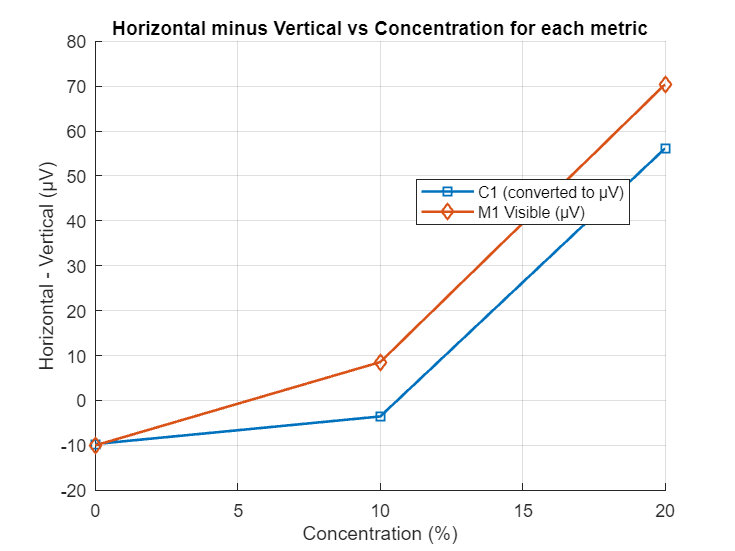

title('Horizontal minus Vertical vs Concentration for each metric');
grid on;

It would be great to have more datapoints at different concentrations. we believe that the 0 concentration datapoint (empty just water) was not so good as there were some bubbles, which were not as present in the other samples. however, if we had more datapoints about the concentration dependance we could extrapolate and figure out the concentration of hemozoid in a sample based on the optical response effect and anisotropic optical properties.

we plan to extract the slop from the 2nd and 3rd datapoints as the "just water" sample can be considered as a baseline (or background noise). when we take a real sample (with unknown concentration of hemozoid) we just measure its optical properties and do linear regression to get its concentration.